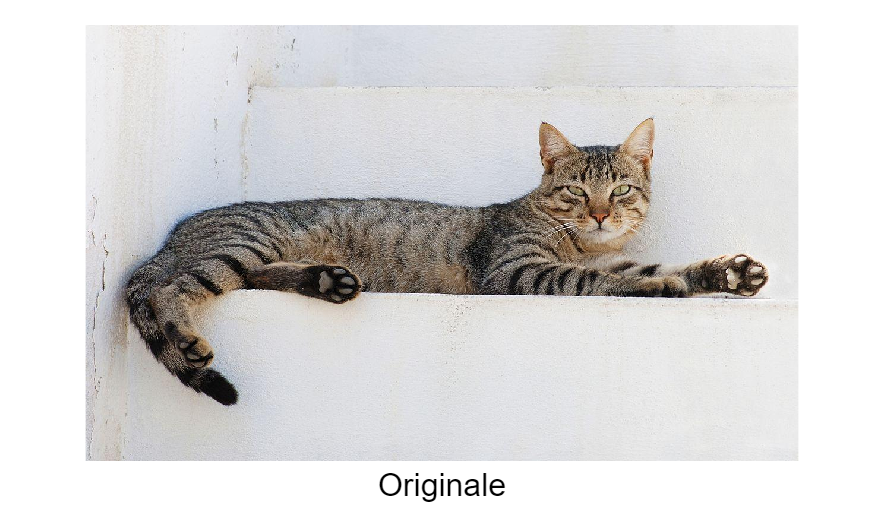

fullFileName = matlab.desktop.editor.getActiveFilename;
folderPath = fileparts(fullFileName);
folderPath = strrep(folderPath, 'MatLab', '');
folderPath = fullfile(folderPath, 'Python/dataset');
folderPath = fullfile(folderPath, 'original');
nome_img = 'Cat_August_2010-4.jpg';
folderPath = fullfile(folderPath, nome_img);

i2 = imread(folderPath);
imshow(i2)
text(size(i2,2)/2, size(i2,1) + 10, 'Originale', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

Applicazione Rumore Gamma

Valor medio b / a

Varianza b/a^2

se diminuisci a aumenta molto il rumore

N.B: rumore deve essere 0-mean: questo che abbiamo messo non lo è, e quindi schiarisce l'immagine in media di E[erlang] = b/a.

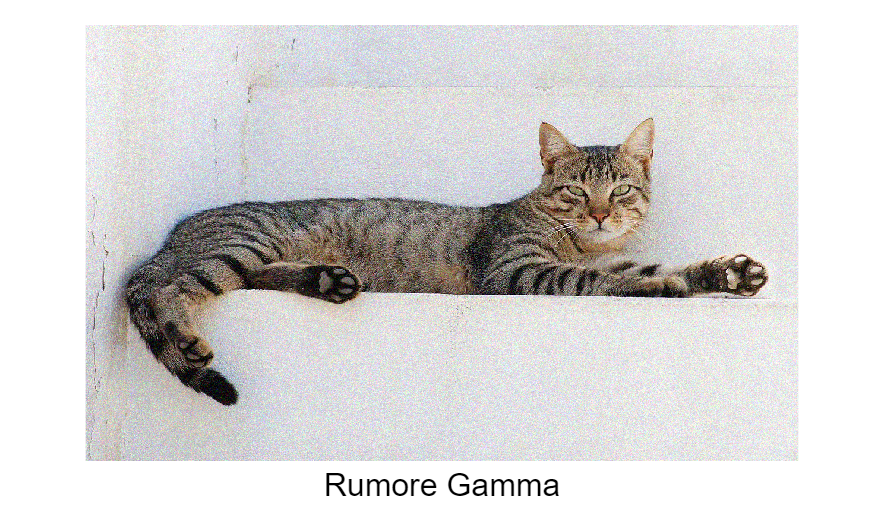

I = im2double(i2);
a = 50;
b = 10;

scale = 1/a;

noiseGamma = gamrnd(b,scale,size(I));
noise_zero_mean = noiseGamma - (b * scale); % !!!!!!!!!
noisy_img = I + noise_zero_mean;
noisy_img = min(max(noisy_img, 0), 1);

imshow(noisy_img)
img_noisy = noisy_img;
text(size(i2,2)/2, size(i2,1) + 10, 'Rumore Gamma', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

Filtro di Weiner

Finestra 3x3 è meglio di 5x5

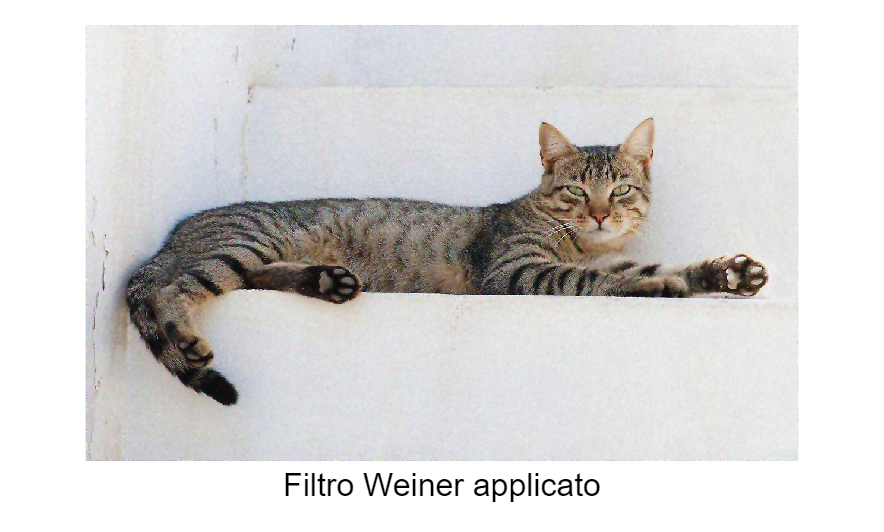

img_denoisedw = img_noisy;
for c = 1:3
    img_denoisedw(:,:,c) = wiener2(noisy_img(:,:,c), [5 5]);
end

imshow(img_denoisedw,[])
text(size(i2,2)/2, size(i2,1) + 10, 'Filtro Weiner applicato', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

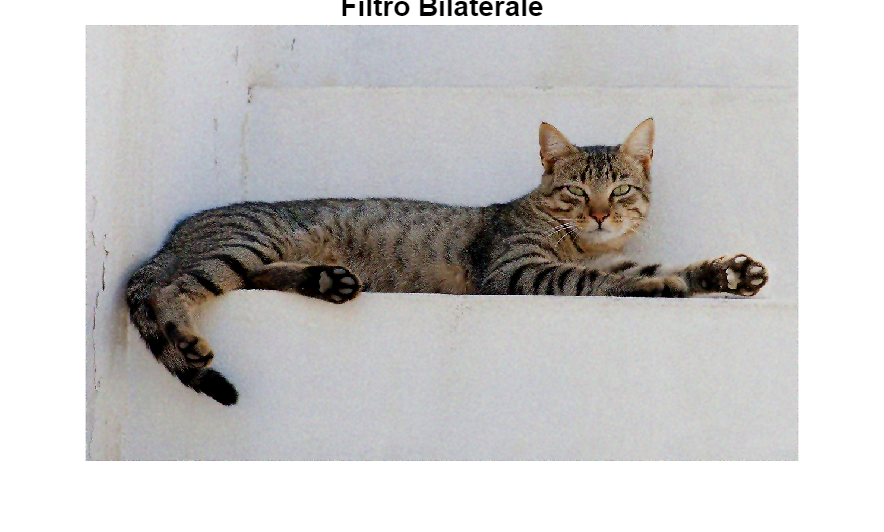

img_denoised = img_denoisedw - 0.1;
imshow(img_denoised, [])
title('Filtro Bilaterale')

% Conversione per confronto corretto
I_originale = im2double(i2);

% PSNR tra originale e immagine rumorosa
[peaksnr1, snr1] = psnr(noisy_img, I_originale)

peaksnr1 = 24.4561

snr1 = 22.4613


% PSNR tra originale e immagine filtrata
[peaksnr2, snr2] = psnr(img_denoised, I_originale)

peaksnr2 = 19.4223

snr2 = 17.4275


[peaksnr3, snr3] = psnr(img_denoisedw, I_originale)

peaksnr3 = 29.4497

snr3 = 27.4548